- Utilice las funciones de RVC para construir un modelo en alambres. 1 

    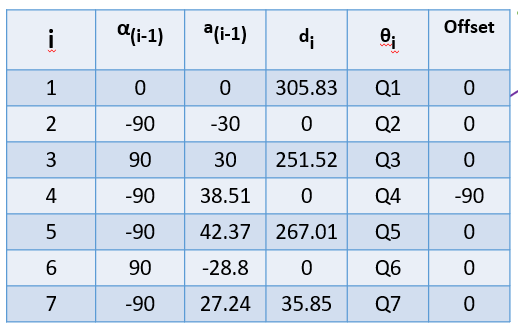

syms q1 q2 q3 q4 q5 q6 q7;

q = [0 0 0 0 0 0 0];

L(1) = Link('revolute','alpha', 0,      'a', 0,   'd',305.83,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,  'a', -30,    'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', pi/2,      'a', 30, 'd',251.52,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha', -pi/2,      'a', 38.51, 'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', -pi/2,      'a', 42.37,   'd',267.01,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', pi/2,      'a', -28.8,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(7) = Link('revolute','alpha', -pi/2,      'a', 27.24,   'd',35.85,   'offset', 0,   'modified', 'qlim',[-pi pi]);

plot_options = {'workspace',[-50 50 -50 50 -50 50],'scale',1, 'view',[150 10]};

R = SerialLink(L,'name','Robot 6','plotopt',plot_options)

 
R = 
 
Robot 6 (7 axis, RRRRRRR, modDH, fastRNE)                        
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      305.8|          0|          0|          0|
|  2|         q2|          0|        -30|     -1.571|          0|
|  3|         q3|      251.5|         30|      1.571|          0|
|  4|         q4|          0|      38.51|     -1.571|     -1.571|
|  5|         q5|        267|      42.37|     -1.571|          0|
|  6|         q6|          0|      -28.8|      1.571|          0|
|  7|         q7|      35.85|      27.24|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
 

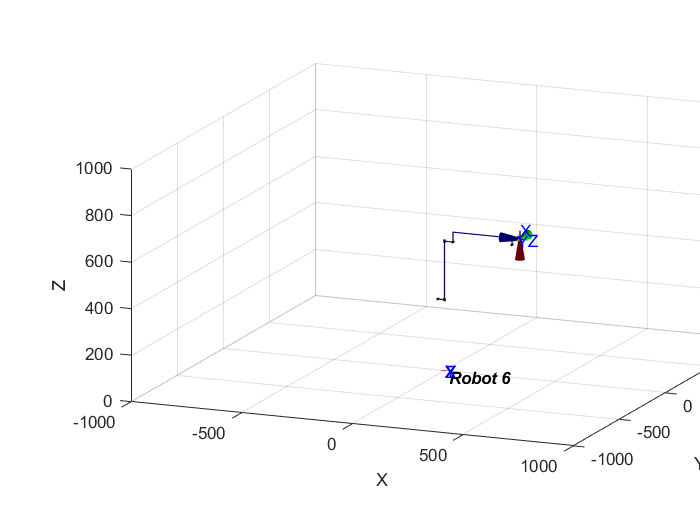


hold on
trplot(eye(4), 'width',2,'arrow');hold on;
axis([-1000 1000 -1000 1000 0 1000])
R.teach(q)
arrow3([0,0,0],[0 0 2],'5',0,'r');